# State estimation using an observer

## Review of state feedback controller 

For a dynamical system 


$$\dot{\mathbf{x}} = A\mathbf{x}  + Bu  \\
y = C\mathbf{x} + Du$$


A state feedback controller modifies the input from $u$ to $u - K_c \mathbf{x}$ as shownn in the figure below. That is, we measure the entire state of the system, and use it to modify the input to achieve our control objective.  

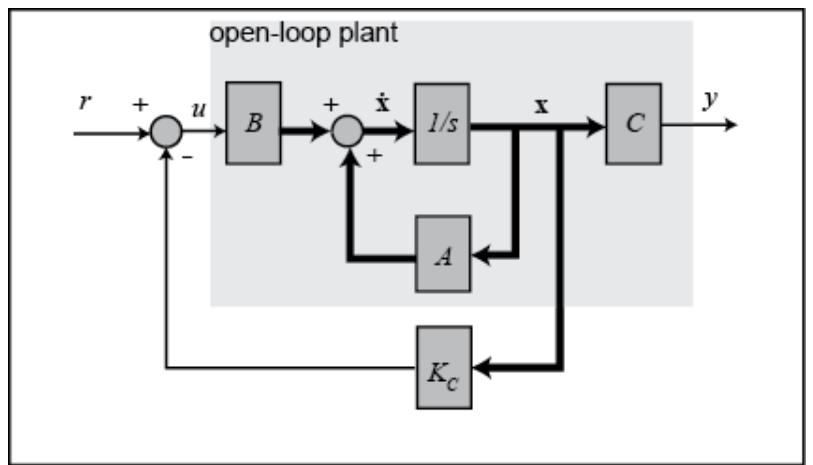

We saw two ways of computing $K_c$: 1) Pole-placement method, and 2) LQR method. 

We will use Simulink today. We will first implement the state feedback controller in Simulink. 

**Walk through:** 

- dc_motor.slx

- state_feedback_controller.slx 

**Exercise: **

- Starting from dc_motor.slx, implement a state feedback controller as in state_feedback_controller.slx 

### Model setup

J = 0.01; %kg.m^2
b = 0.1; %N.m.s 
K = 0.01; %V/rad/s
R = 1; %Ohm
L = 0.5; %H


%setting up the state space model 
A = [-b/J, K/J; -K/L -R/L]; 
B = [0; 1/L]; 
C = [1 0];
D = 0;
dcMotorSS = ss(A,B,C,D); 


### Computing feedback gain using pole placement

p1 = -5 + 1i; 
p2 = conj(p1); 
Kc = place(A,B,[p1,p2]);
sys_cl = ss(A-B*Kc, B, C,D); 
Nbar = 1/dcgain(sys_cl); %scaling factor at the input to obtain steady state output at 1 

## Observer design

### What is state estimation? 

- State estimation is the process of using observed data ($y
$) to infer the internal states of a system.

- It involves combining sensor measurements with a model of the system to estimate the state variables.

### Why do we need to estimate state?

- Not all states are measurable and/or sensors may be too expensive. 

- Noise in measurements (we will dive into this when we talk about Kalman filters). 

- System reliability/security:  estimate even when we have sensors to hedge against tampering 

- Predictive manintenance: estiamte the future states assuming known future inputs 

- For simplified modeling, state estimation bridges the gap between theoretical models and physical plants

### Theory behind state estimation

- If we have a good knowledge of the system, then we know the matries $A,B,C$ and $D$ which characterize the dynamics and measurements. 

- Because we are providing the input, we know the input $u$.

- What we don't know: 1) Initial state $\mathbf{x}_0$ of the system, 2) Information about external disturbances 

State estimation should compensate for the above unknown quantities. We will accomplish this by 

- Estimate the output using our knowledge of the system and the input (this amounts to performing a real-time simulation of the system)


$$\dot{\hat{\mathbf{x}}} =  A\hat{\mathbf{x}} + Bu \\
\hat{y} = C\hat{\mathbf{x}}$$


- Compare out estimated output with the real output 


$$e_y = y - \hat{y}$$


- If $e \not = 0$, then $\hat{\mathbf{x}} \not = \mathbf{x}$, and we need to update our estimate. We will use a linear update method as follows 


$$\dot{\hat{\mathbf{x}}} =  A\hat{\mathbf{x}} + Bu  + L(y-\hat{y})$$


- Note that $L$ is a column vector which dimension equal to that of $\dot{\hat{\mathbf{x}}}$. The question now is, how to compute $L$? 

- If we subtract the above equation from the state equation, we get 


$$\dot{\mathbf{x}} = A\mathbf{x}  + Bu\\
 -\\
\dot{\hat{\mathbf{x}}} =  A\hat{\mathbf{x}} + Bu  + L(y-\hat{y}) \\
\dot{\mathbf{x}} -  \dot{\hat{\mathbf{x}}} = A(\mathbf{x} - \hat{\mathbf{x}}) - L(y-\hat{y}) \\
= A(\mathbf{x} - \hat{\mathbf{x}}) - LC(\mathbf{x} - \hat{\mathbf{x}}) \\
\Rightarrow \dot{\mathbf{x}} -  \dot{\hat{\mathbf{x}}}  = (A-LC)(\mathbf{x} - \hat{\mathbf{x}}) $$


- Denote $$e = \mathbf{x} -  \hat{\mathbf{x}} $ $, the error between the state and the estimated state vectors. Then the above equation describes the dynamics of this error vector. 

- If we don't know $\mathbf{x}_0$, then $e(0) \not = 0$. However, if the eigenvalues of $A-LC$ are on the lef-side of the complex plane, then the above system will be stable and the error will converge to zero (assuming no external disturbances). 

- If we tranpose the error dynamics equation on both sides, we get 


$$\dot{\mathbf{x}}^T -  \dot{\hat{\mathbf{x}}}^T  = (\mathbf{x} - \hat{\mathbf{x}})^T(A^T-C^TL^T) $$


- The above equation has the same dynamics, and we want the eigenvalues of $(A^T-C^TL^T) $ to be on the left half of the complex plane. We already saw we can do this by using MATLAB's `place()` function. 

q1 = -5 + 3i; 
q2 = conj(q1); 
Lc = place(A',C', [q1,q2])
[vectors,values] = eig(A-Lc'*C); 
diag(values)

Lc =    -2.0000   17.9800


ans =   -5.0000 + 3.0000i
  -5.0000 - 3.0000i


### Exercise

Starting from the dc_motor.slx file, implement the state observer model.